# P3

clc
clear
close all

% 基本参数
Gqn0 = [16,64,256,1024,4096,16384,65536,262144]*1e-6;
vv   = [10,20,40,60];   % 车速m/s
n0   = 0.1;             % 参考空间频率


% 工况选择
Gqn0 = Gqn0(1);   % 选择路面等级
v    = vv(4);     % 选择车速

% simulink增益设置
k1 = 40*sqrt(Gqn0(1)*v);

% white noise
noise_power = 0.01;                % 噪声功率
sample_time = 0.001;                % 采样时间
seed = 23341;                      % 随机种子

% 运行simulink模型
options=simset('Srcworkspace','current');
out=sim('P3_son.slx',[0,10]);

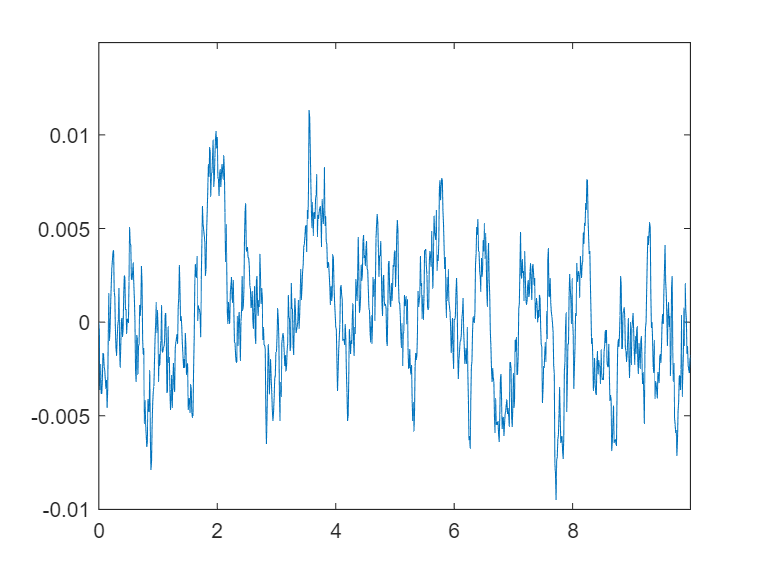

% 绘制路面不平度随时间变化
figure(1)
time           = out.simout.Time;
roud_roughness = out.simout.Data;
plot(time,roud_roughness);